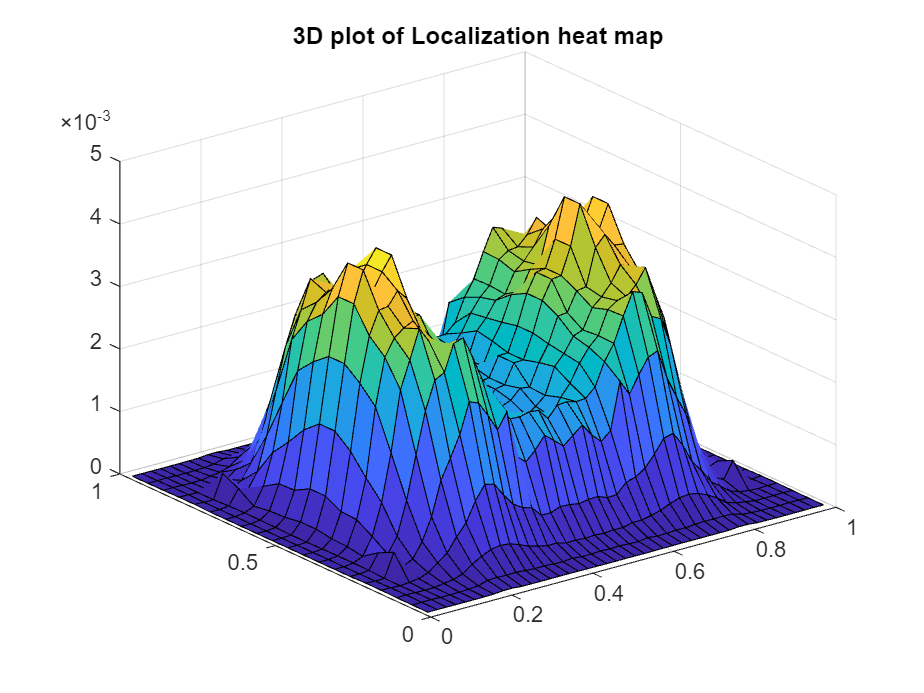

clearvars -except gap_y gap_x Result_cat_sym aspt_ratio low_bd up_bd ...
    ori ter left right cell_outline Filefolder

maskArea_ratio = 0.10;

gap_x = gap_y/aspt_ratio;
% get the information from 2D heat map image
heatmap_raw = histcounts2(Result_cat_sym(:,1),Result_cat_sym(:,2),'XBinEdges',-0.5:gap_y/aspt_ratio:0.5,'YBinEdges',-0.5:gap_y:0.5,...
    'Normalization','probability');
heatmap_raw = heatmap_raw';

x = (0:gap_x:1);
x = Get_bincenter(x);

y = (0:gap_y:1);
y = Get_bincenter(y);

[X, Y] = meshgrid(x,y);
figure
surf(X,Y,heatmap_raw)
title('3D plot of Localization heat map')

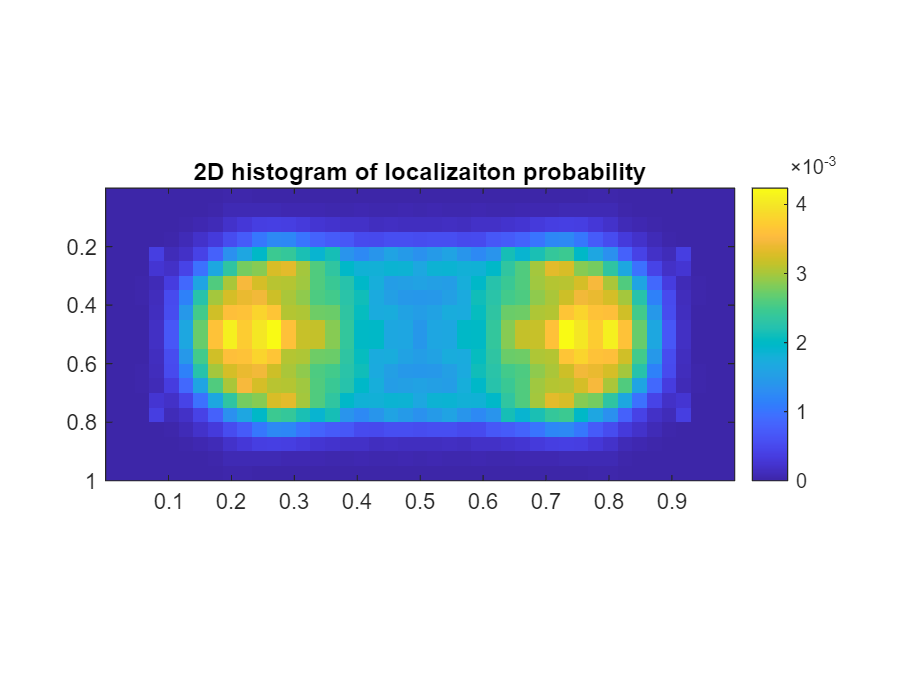


figure
imagesc(x,y,heatmap_raw)
colorbar
pbaspect([aspt_ratio 1 1])
title('2D histogram of localizaiton probability')

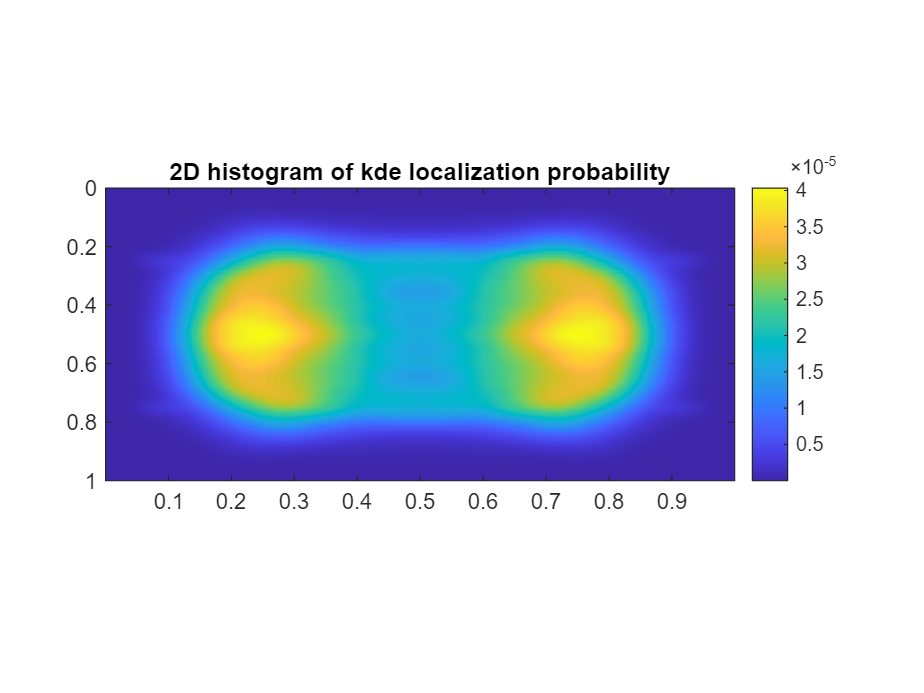

% %Interpolation to get finner grids 
% 
% set up scaling factor
scale_rate = 10;

xq = (0:gap_x/scale_rate:1);
xq = Get_bincenter(xq);

yq = (0:gap_y/scale_rate:1);
yq = Get_bincenter(yq);

%kde to get finner grids 
gridx = linspace(-0.5,0.5,1/gap_y*aspt_ratio*scale_rate);
gridy = linspace(-0.5,0.5,1/gap_y*scale_rate);
[X,Y] = meshgrid(gridx, gridy);
X = X(:);
Y = Y(:);
pts = [X Y];
clear gridx gridy X Y
[heatmap_kde,~] = ksdensity(Result_cat_sym,pts);
heatmap_kde = reshape(heatmap_kde,[1/gap_y*scale_rate, 1/gap_y*aspt_ratio*scale_rate]);
heatmap_kde = heatmap_kde/sum(heatmap_kde,'all');
figure
imagesc(xq, yq, heatmap_kde)
colorbar
pbaspect([aspt_ratio 1 1])
title('2D histogram of kde localization probability')

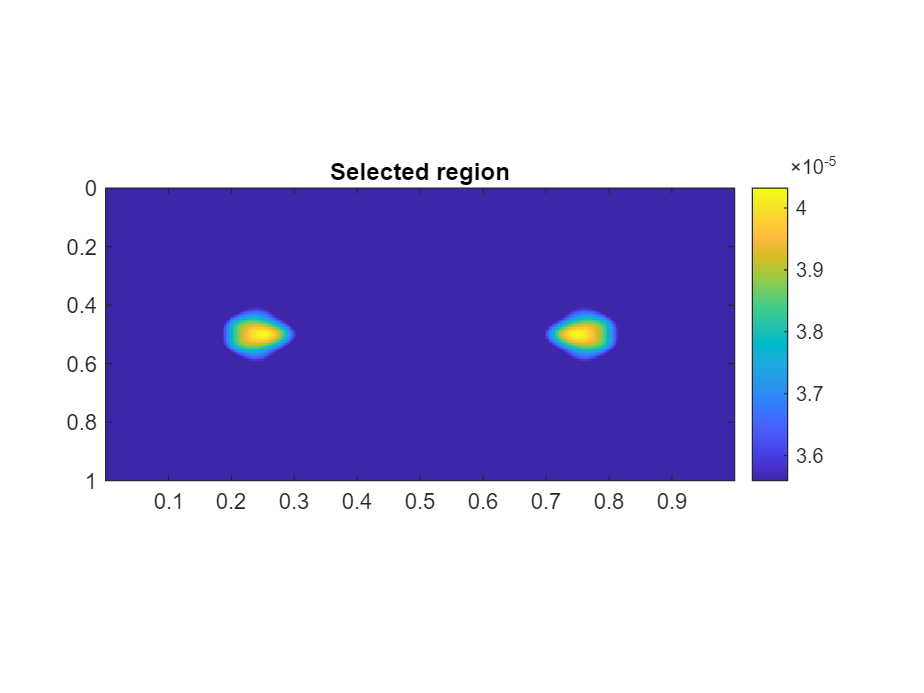

heatmap_fine = heatmap_kde;
% get the hot region with specified integrating probability 
[region_mac,perMax] = Get_HotRegion(heatmap_fine,maskArea_ratio);
%% result check up
% a = find(heatmap_intp>perMax*max(heatmap_intp,[],'all'));
% a = sum(heatmap_intp(a))
% clear a

% plot the macrodoamin region 
md_region = heatmap_fine;
md_region(md_region<perMax*max(md_region,[],'all')) = NaN;
figure
imagesc(xq,yq,md_region)
colorbar
pbaspect([aspt_ratio 1 1])
title('Selected region')

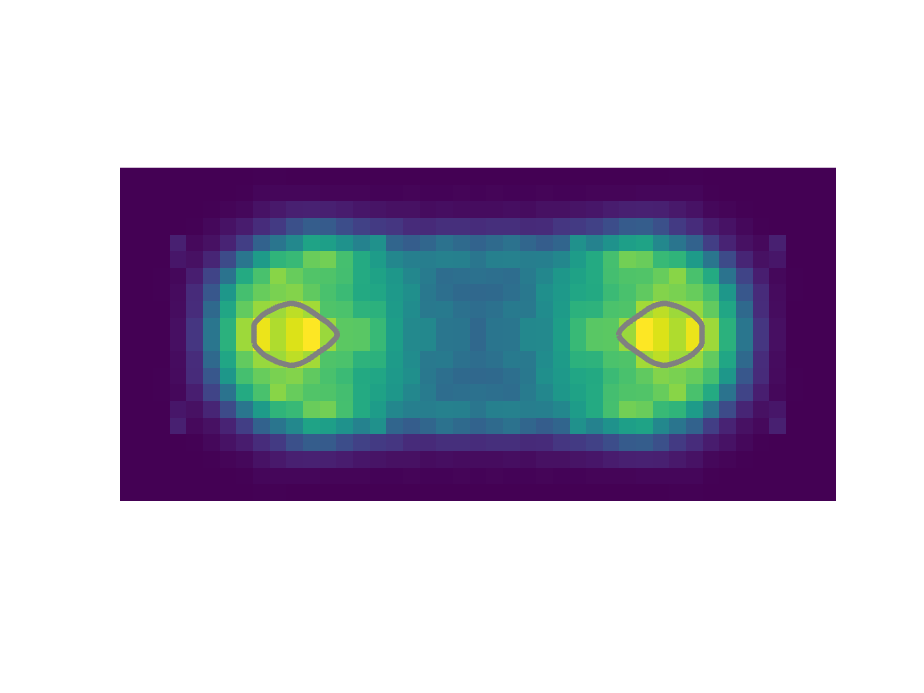


test = Get_boundary(heatmap_fine,region_mac);
test2 = zeros(height(test),2);
for i=1:height(test)
    test2(i,1) = yq(test(i,1));
    test2(i,2) = xq(test(i,2));
end

idx = dbscan(test2,0.01,3);
% figure
% gscatter(test2(:,2),test2(:,1),idx);
id_group = unique(idx);
area_list = zeros(numel(id_group),1);
for ii = 1:numel(id_group)
    grp_id = idx==ii;
    grp = test2(grp_id,:);
    grp_bd = boundary(grp(:,1),grp(:,2));
    area_list(ii) = polyarea(grp(grp_bd,1),grp(grp_bd,2));
end
area_list = area_list/(gap_x*gap_y);
grp_final = find(area_list>=1);

figure
hold on
% imagesc(xq,yq,heatmap_intp)
imagesc(x,y,heatmap_raw)
% colorbar
pbaspect([aspt_ratio 1 1])
for ii = 1:numel(grp_final)
    sel_grp = grp_final(ii);
    sel_id  = idx == sel_grp;
    buff = test2(sel_id,:);
    buff2 = boundary(buff(:,1),buff(:,2));
    buff = buff(buff2,:);
    plot(buff(:,2),buff(:,1),'LineWidth',2.5,'Color',[0.5 0.5 0.5])
end
colormap(slanCM('viridis'))
axis off


id_final = ismember(idx,grp_final);
test2 = test2(id_final,:);
clear idx id_group area_list ii grp_id grp grp_bd grp_rm id_rm 
clear sel_grp sel_id buff buff2

figure
hold on;
imagesc(x,y,heatmap_raw)
pbaspect([aspt_ratio 1 1])
idx = dbscan(test2,0.01,3);
id_group = unique(idx);
for ii = 1:numel(id_group)
    grp_id = idx==ii;
    grp = test2(grp_id,:);
    grp_bd = boundary(grp(:,1),grp(:,2));
    plot(grp(grp_bd,2),grp(grp_bd,1),'LineWidth',2.5,'Color',[0.5 0.5 0.5])
end
colormap(slanCM('viridis'))
axis off

% save demo figure in svg format
fld = uigetdir('L:\MIGRATED\Lab_Members\Xiaofeng_Dai\Manuscript\Nucleoid_Viscosity\Dataset\LAM022_24h_NanocageTracking_withHeater');
print(gcf,...
    fullfile(fld, ['Heatmap_ori' '.' 'svg']),...
    '-dsvg', '-vector');

clear fld
save(strcat(Filefolder,filesep,'Heatmaps',filesep,'Ori_boundary.mat'),'test2')

# **Function**

### Get bin center from arithmetic progression array

function Bincenter = Get_bincenter(X)
    Bincenter = zeros(length(X)-1,1);
    for i=1:length(X)-1
        Bincenter(i) = 0.5*(X(i) + X(i+1));
    end 
end


### Calculate nucleoid region and percentage of maximum occurancy

function [region_select, perMax] = Get_HotRegion(heatmap,thres,acc)
    if nargin==2
        acc = 5e-4;
    end
    sum_area = 0;
    cross_val = 0.5;
    cross_bd = [0,1];
    while abs(sum_area-thres)>acc
        ind = heatmap>cross_val*max(heatmap,[],'all');
        sum_area = sum(heatmap(ind));
        if abs(sum_area-thres)>acc
            if sum_area>thres
                cross_bd(1) = cross_val;
                cross_val = 0.5*(cross_val+cross_bd(2));
            else
                cross_bd(2) = cross_val;
                cross_val = 0.5*(cross_val+cross_bd(1));
            end
        end
    end
    [ind1, ind2] = find(heatmap>cross_val*max(heatmap,[],'all'));
    region_select = [ind1,ind2];
    perMax = cross_val;
end


### Get boundary of macrodomain region 

function Boundary = Get_boundary(heatmap,region_mac)
    BW = heatmap;
    for j =1:height(region_mac)
        a = region_mac(j,1);
        b = region_mac(j,2);
        BW(a,b) = 1;
    end
    BW(BW~=1) = 0;
    ind = zeros(height(region_mac),1);
    for i=1:height(region_mac)
        indr = region_mac(i,1);
        indc = region_mac(i,2);
        buff = BW(indr,indc) + BW(indr-1,indc) + BW(indr+1,indc) + BW(indr,indc-1) + BW(indr,indc+1);
        if buff<5
            ind(i) = 1;
        end
    end
    Boundary = region_mac(ind==1,:);
end